# Summary of Alpha Values from VBWIM

% Search through VBResults from WIM and SIM and perform compare plot! Scatter plot
clear, clc, close all

D = linspecer(30);  
%Load WIM results
    load('VBResultsWIMFlamattprBeta4_2Max.mat')
%load('VBResultsAlphaq(Q1=0.55etQ2=0.35)WIMFlamattprBeta4_2Max.mat')
Model = "SIA";
BlockM = "Weekly";
VBR = VBResults.(Model).(BlockM);
VBRMerged = VBR;
%Load SIM results (Congested)
    load('VBResultsSimFlamattJuin26Congested20%prBeta4_2.mat')
%load('VBResultsAlphaq(Q1=0.55etQ2=0.35)SimFlamattJuin26Congested20%prBeta4_2.mat')
VBR2 = VBResults.(Model).Yearly;
Jammed = true;
Calibrated = true;
Traffic = "ClassOW"; %Class or ClassOW or All
%Load SIM results (Jammed)
if Jammed
    load('VBResultsSimFlamattJuin26Jammed2%prBeta4_2.mat')
%load('VBResultsAlphaq(Q1=0.55etQ2=0.35)SimFlamattJuin26Jammed2%prBeta4_2.mat')
VBR3 = VBResults.(Model).Yearly;
end

VBRMerged.Properties.VariableNames('Class') =  {'WIMClass'};
VBRMerged.Properties.VariableNames('ClassOW') =  {'WIMClassOW'};
VBRMerged.Properties.VariableNames('All') =  {'WIMAll'};
keys = {'Type','SubType','Width','Layout','Support','Trans','AE','Traffic','Span'};

VBR2.Properties.VariableNames('Class') =  {'WIMClass'};
VBR2.Properties.VariableNames('ClassOW') =  {'WIMClassOW'};
VBR2.Properties.VariableNames('All') =  {'WIMAll'};
VBRMerged.SIMCongestedClassOW(:) = NaN;
VBRMerged.SIMCongestedClass(:) = NaN;
VBRMerged.BestFitSIMCongestedClassOW(:) = strings(height(VBRMerged),1);
VBRMerged.BestFitSIMCongestedClassOW(:) = missing;
VBRMerged.BestFitSIMCongestedClass(:) = strings(height(VBRMerged),1);
VBRMerged.BestFitSIMCongestedClass(:) = missing;
[tf,loc] = ismember(VBR2(:,keys),VBRMerged(:,keys));
VBRMerged.SIMCongestedClassOW(loc(tf)) = VBR2.WIMClassOW(tf);
VBRMerged.SIMCongestedClass(loc(tf)) = VBR2.WIMClass(tf);
VBRMerged.BestFitSIMCongestedClassOW(loc(tf)) = VBR2.BestFitClassOW(tf);
VBRMerged.BestFitSIMCongestedClass(loc(tf)) = VBR2.BestFitClass(tf);
newRows = VBR2(~tf,:);
newRows.SIMCongestedClassOW = newRows.WIMClassOW;
newRows.WIMClassOW(:) = NaN;
newRows.SIMCongestedClass = newRows.WIMClass;
newRows.WIMClass(:) = NaN;
newRows.WIMAll(:) = NaN;
newRows.BestFitSIMCongestedClassOW = newRows.BestFitClassOW;
newRows.BestFitClassOW(:) = missing;
newRows.BestFitSIMCongestedClass = newRows.BestFitClass;
newRows.BestFitClass(:) = missing;
VBRMerged = [VBRMerged; newRows(:,VBRMerged.Properties.VariableNames)];

if Jammed
VBR3.Properties.VariableNames('Class') =  {'WIMClass'};
VBR3.Properties.VariableNames('ClassOW') =  {'WIMClassOW'};
VBR3.Properties.VariableNames('All') =  {'WIMAll'};
VBRMerged.SIMJammedClassOW(:) = NaN;
VBRMerged.SIMJammedClass(:) = NaN;
VBRMerged.BestFitSIMJammedClassOW(:) = strings(height(VBRMerged),1);
VBRMerged.BestFitSIMJammedClassOW(:) = missing;
VBRMerged.BestFitSIMJammedClass(:) = strings(height(VBRMerged),1);
VBRMerged.BestFitSIMJammedClass(:) = missing;
[tf,loc] = ismember(VBR3(:,keys),VBRMerged(:,keys));
VBRMerged.SIMJammedClassOW(loc(tf)) = VBR3.WIMClassOW(tf);
VBRMerged.SIMJammedClass(loc(tf)) = VBR3.WIMClass(tf);
VBRMerged.BestFitSIMJammedClassOW(loc(tf)) = VBR3.BestFitClassOW(tf);
VBRMerged.BestFitSIMJammedClass(loc(tf)) = VBR3.BestFitClass(tf);
newRows = VBR3(~tf,:);
newRows.SIMJammedClassOW = newRows.WIMClassOW;
newRows.WIMClassOW(:) = NaN;
newRows.SIMJammedClass = newRows.WIMClass;
newRows.WIMClass(:) = NaN;
newRows.BestFitSIMJammedClassOW = newRows.BestFitClassOW;
newRows.BestFitClassOW(:) = missing;
newRows.BestFitSIMJammedClass = newRows.BestFitClass;
newRows.BestFitClass(:) = missing;
newRows.SIMCongestedClassOW(:) = NaN;
newRows.SIMCongestedClass(:) = NaN;
newRows.BestFitSIMCongestedClassOW(:) = missing;
newRows.BestFitSIMCongestedClass(:) = missing;
VBRMerged = [VBRMerged; newRows(:,VBRMerged.Properties.VariableNames)];
end

% Part for the Sim Congested traffic that is calibrated
if Calibrated
% Find Ratio (Correction Factor)
VBRMerged.CorrFClassOW = VBRMerged.WIMClassOW./VBRMerged.SIMCongestedClassOW;
VBRMerged.CorrFClass = VBRMerged.WIMClass./VBRMerged.SIMCongestedClass;

VBSimOut = VBRMerged(isnan(VBRMerged.CorrFClass),:);
VBRSIMwWIM = VBRMerged(~isnan(VBRMerged.CorrFClass),:);
VBSimOutCor = VBSimOut;
% Look through and correct
for i = 1:height(VBSimOut)
    [a, b] = max(sum(VBSimOut{i,1:9} == VBRSIMwWIM{:,1:9},2));
    % 'a' is IL comparison score and 'b' is index
    VBSimOutCor.CorrFClassOW(i) = VBRSIMwWIM.CorrFClassOW(b);
    VBSimOutCor.SIMCongestedClassOW(i) = VBSimOut.SIMCongestedClassOW(i)*VBRSIMwWIM.CorrFClassOW(b);
    VBSimOutCor.CorrFClass(i) = VBRSIMwWIM.CorrFClass(b);
    VBSimOutCor.SIMCongestedClass(i) = VBSimOut.SIMCongestedClass(i)*VBRSIMwWIM.CorrFClass(b);
    
end

[tf,loc] = ismember(VBSimOutCor(:,keys),VBRMerged(:,keys));
VBRMerged.SIMCongestedClassOW(loc(tf)) = VBSimOutCor.SIMCongestedClassOW(tf);
VBRMerged.SIMCongestedClass(loc(tf)) = VBSimOutCor.SIMCongestedClass(tf);
VBRMerged.CorrFClassOW(loc(tf)) = VBSimOutCor.CorrFClassOW(tf);
VBRMerged.CorrFClass(loc(tf)) = VBSimOutCor.CorrFClass(tf);
VBRMerged.SIMCongestedCorrected(loc(tf))=1;
end

% Rajout du cas gros chantier
GrosChantier =false;
if GrosChantier
load('VBResultsWIMFlamattprBeta3_21.mat')
%load('VBResultsAlphaq(Q1=0.55etQ2=0.35)WIMFlamattprBeta3_21.mat')
VBRGC = VBResults.(Model).(BlockM);
VBRMerged.WIMClassOW(strcmp(VBRMerged.Width,"Wid9")) = VBRGC.ClassOW;
VBRMerged.SIMCongestedClassOW(strcmp(VBRMerged.Width,"Wid9")) = NaN;
VBRMerged.SIMCongestedClass(strcmp(VBRMerged.Width,"Wid9")) = NaN;
end

SpanName = int2str(VBRMerged.Span);
SpanName((SpanName(:,1)==' '),1) = '0';
SpanName = strcat('S',SpanName);
VBRMerged.Name = VBRMerged.Type + '.' + VBRMerged.SubType + '.' + VBRMerged.Width + '.' + VBRMerged.Layout + '.' + VBRMerged.Support + '.' + VBRMerged.Trans + '.' + VBRMerged.AE + '.' + SpanName;


%St = [4 6 8 10 15 20 25 30 40 50 60 70 80]; % no 2 meters
St = [50 51 52 53 54 55]; % Flamatt
%Lab = {'4', '6', '8', '10', '15', '20', '25', '30', '40', '50', '60', '70', '80'}; % no 2 meters
Lab = {'1', '2', '3', '4', '5', '6'}; % Flamatt
%Lab = {'4', '5', '6', '8', '10', '15', '20', '25', '30', '40', '50', '60', '70', '80'}; % no 2 meters
%Lab = {'20', '30', '40', '50', '60', '70', '80'}; % no 2 meters
%Fi = [1 2 3 4 5  6  7  8  9  10 11 12 13]; % no 2 meters
Fi = [1 2 3 4 5  6]; % Flamatt
%Fi = [1 2 3 4 5  6  7  8  9  10 11 12 13 14]; % no 2 meters
%Fi = [1 2 3 4 5  6  7 ]; % no 2 meters

[~, idx] = ismember(VBRMerged.Span,St);
xdataTr = Fi(idx);
%Traffic = 'Autre';


## Main Plot

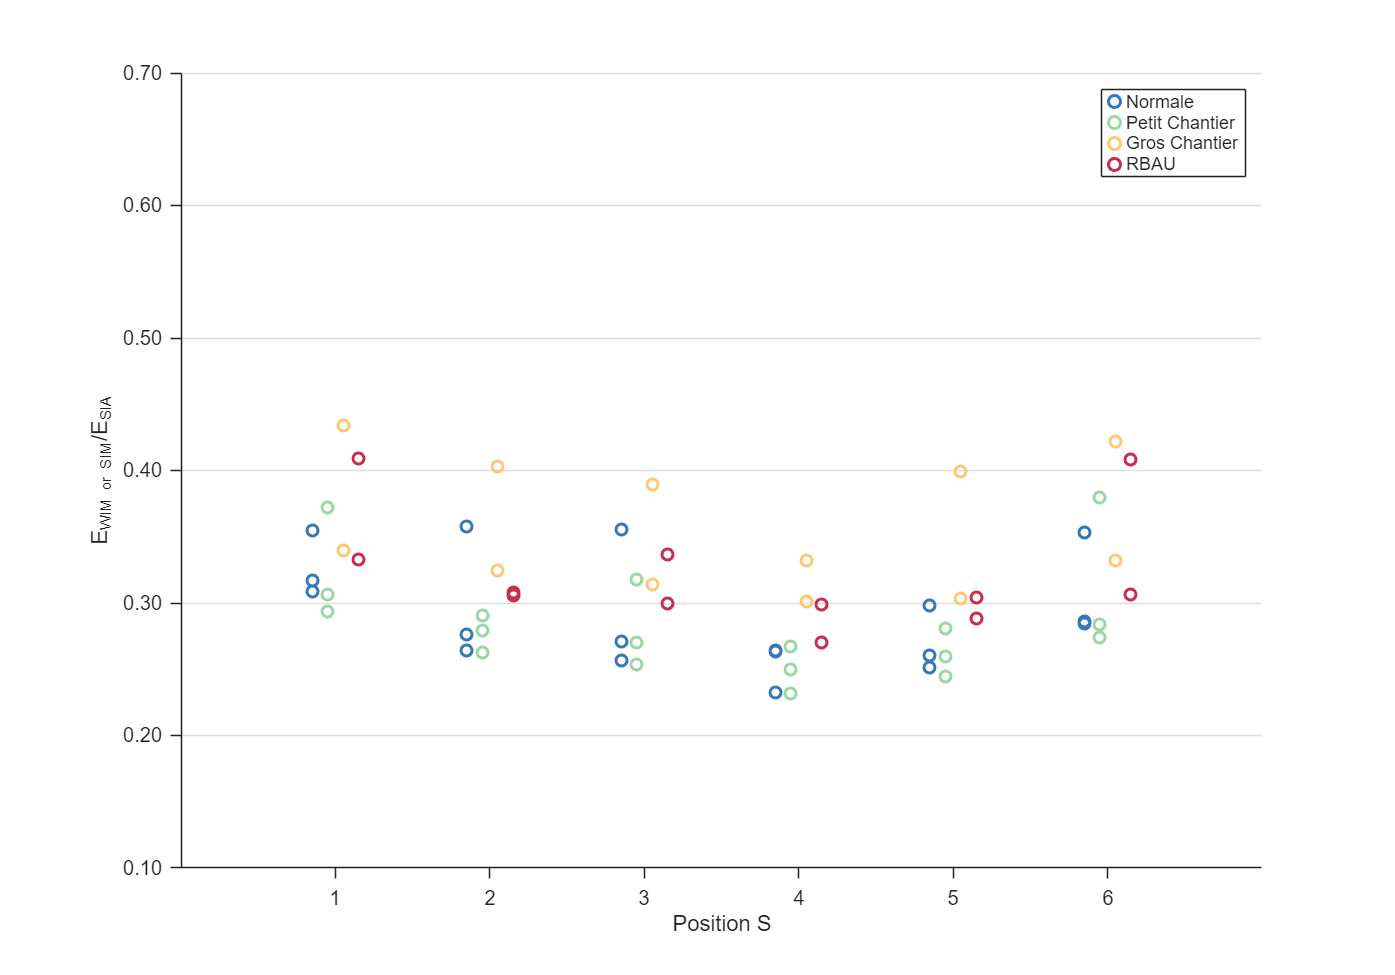

figure('Position',[325 225 930 650]); hold on;

if strcmp(Traffic,'Class')
    PlWIM=scatter(xdataTr-0.2,VBRMerged.WIMClass,30,D(6,:),'DisplayName','WIM Class','LineWidth',1.5);
    PlSIMCongested=scatter(xdataTr(~strcmp(VBRMerged.Layout,"RBAU")),VBRMerged.SIMCongestedClass(~strcmp(VBRMerged.Layout,"RBAU")),30,D(28,:),'DisplayName','SIM Congested 20% Class','LineWidth',1.5);
    PlSIMCongested=scatter(xdataTr(strcmp(VBRMerged.Layout,"RBAU")),VBRMerged.SIMCongestedClass(strcmp(VBRMerged.Layout,"RBAU")),30,D(28,:),'DisplayName','SIM Congested 20% Class Calibrated','LineWidth',1.5);
    if Jammed
    PlSIMJammed=scatter(xdataTr+0.2,VBRMerged.SIMJammedClass,30,D(1,:),'DisplayName','SIM Jammed 2% Class','LineWidth',1.5);
    end
elseif strcmp(Traffic,'ClassOW')
    PlWIM=scatter(xdataTr-0.2,VBRMerged.WIMClassOW,30,D(21,:),'DisplayName','WIM Class+','LineWidth',1.5);
    if GrosChantier
    PlWIMGC=scatter(xdataTr(strcmp(VBRMerged.Width,"Wid9"))-0.2,VBRMerged.WIMClassOW(strcmp(VBRMerged.Width,"Wid9")),80,D(19,:),'DisplayName','WIM Major construction works','LineWidth',1.5);
    end
    PlSIMCongested=scatter(xdataTr(~strcmp(VBRMerged.Layout,"RBAU")),VBRMerged.SIMCongestedClassOW(~strcmp(VBRMerged.Layout,"RBAU")),30,D(28,:),'DisplayName','SIM Congested 20% Class+','LineWidth',1.5);
    PlSIMCongestedCali=scatter(xdataTr(strcmp(VBRMerged.Layout,"RBAU")),VBRMerged.SIMCongestedClassOW(strcmp(VBRMerged.Layout,"RBAU")),30,D(24,:),'DisplayName','SIM Congested 20% Class+ Calibrated','LineWidth',1.5);
    if Jammed
    PlSIMJammed=scatter(xdataTr+0.2,VBRMerged.SIMJammedClassOW,30,D(1,:),'DisplayName','SIM Jammed 2% Class+','LineWidth',1.5);
    end
elseif strcmp(Traffic,'All')
    PlWIM=scatter(xdataTr-0.2,VBRMerged.WIMAll,30,'Black','DisplayName','WIM All','LineWidth',1.5);
    PlSIMCongested=scatter(xdataTr(~strcmp(VBRMerged.Layout,"RBAU")),VBRMerged.SIMCongestedClassOW(~strcmp(VBRMerged.Layout,"RBAU")),30,D(28,:),'DisplayName','SIM Congested 20% Class+','LineWidth',1.5);
    PlSIMCongested=scatter(xdataTr(~strcmp(VBRMerged.Layout,"RBAU")),VBRMerged.SIMCongestedClassOW(strcmp(VBRMerged.Layout,"RBAU")),30,D(28,:),'DisplayName','SIM Congested 20% Class+ Calibrated','LineWidth',1.5);
    if Jammed
    PlSIMJammed=scatter(xdataTr+0.2,VBRMerged.SIMJammedClassOW,30,D(1,:),'DisplayName','SIM Jammed 2% Class+','LineWidth',1.5);
    end
elseif strcmp(Traffic,'Autre')
     ValeurAutre.Normale(:,1) = [xdataTr(strcmp(VBRMerged.Width,"Wid16")),xdataTr(strcmp(VBRMerged.Width,"Wid16")),xdataTr(strcmp(VBRMerged.Width,"Wid16"))]';
     ValeurAutre.Normale(:,2) = [VBRMerged.WIMClassOW(strcmp(VBRMerged.Width,"Wid16"));VBRMerged.SIMCongestedClassOW(strcmp(VBRMerged.Width,"Wid16"));VBRMerged.SIMJammedClassOW(strcmp(VBRMerged.Width,"Wid16"))];
     ValeurAutre.PtCh(:,1) = [xdataTr(strcmp(VBRMerged.Width,"Wid15")&strcmp(VBRMerged.Layout,"Bi")),xdataTr(strcmp(VBRMerged.Width,"Wid15")&strcmp(VBRMerged.Layout,"Bi")),xdataTr(strcmp(VBRMerged.Width,"Wid15")&strcmp(VBRMerged.Layout,"Bi"))]';
     ValeurAutre.PtCh(:,2) = [VBRMerged.WIMClassOW(strcmp(VBRMerged.Width,"Wid15")&strcmp(VBRMerged.Layout,"Bi"));VBRMerged.SIMCongestedClassOW(strcmp(VBRMerged.Width,"Wid15")&strcmp(VBRMerged.Layout,"Bi"));VBRMerged.SIMJammedClassOW(strcmp(VBRMerged.Width,"Wid15")&strcmp(VBRMerged.Layout,"Bi"))];
     ValeurAutre.GrCh(:,1) = [xdataTr(strcmp(VBRMerged.Width,"Wid9")),xdataTr(strcmp(VBRMerged.Width,"Wid9"))]';
     ValeurAutre.GrCh(:,2) = [VBRMerged.WIMClassOW(strcmp(VBRMerged.Width,"Wid9"));VBRMerged.SIMJammedClassOW(strcmp(VBRMerged.Width,"Wid9"))];
     ValeurAutre.RBAU(:,1) = [xdataTr(strcmp(VBRMerged.Width,"Wid15")&strcmp(VBRMerged.Layout,"RBAU")),xdataTr(strcmp(VBRMerged.Width,"Wid15")&strcmp(VBRMerged.Layout,"RBAU"))]';
     ValeurAutre.RBAU(:,2) = [VBRMerged.SIMCongestedClassOW(strcmp(VBRMerged.Width,"Wid15")&strcmp(VBRMerged.Layout,"RBAU"));VBRMerged.SIMJammedClassOW(strcmp(VBRMerged.Width,"Wid15")&strcmp(VBRMerged.Layout,"RBAU"))];
     
     PlNormale=scatter(ValeurAutre.Normale(:,1)-0.15,ValeurAutre.Normale(:,2),30,D(3,:),'DisplayName','Normale','LineWidth',1.5);
     PlPtCh=scatter(ValeurAutre.PtCh(:,1)-0.05,ValeurAutre.PtCh(:,2),30,D(9,:),'DisplayName','Petit Chantier','LineWidth',1.5);
     PlGrCh=scatter(ValeurAutre.GrCh(:,1)+0.05,ValeurAutre.GrCh(:,2),30,D(20,:),'DisplayName','Gros Chantier','LineWidth',1.5);
     PlRBAU=scatter(ValeurAutre.RBAU(:,1)+0.15,ValeurAutre.RBAU(:,2),30,D(28,:),'DisplayName','RBAU','LineWidth',1.5);
end

xlim([0 max(Fi) + 1]); 
ylim([0.1 0.7])
%ylim([2.5 3.5])
%ylim([0 100])

ytickformat('%.2f');
%ytickformat('percentage');
yticks(0.1:0.1:0.7);
%yticks(2.5:0.1:3.5);
%yticks(0:10:100);
set(gca,'TickDir','out');
set(gca,'YGrid','on');
xticks(Fi);
xticklabels(Lab);
%xlabel('Span (m)')
xlabel('Position S')
%title('Monthly Block Maxima Summary')
%ylabel(append('E_{WIM}/E_{',erase(Model,'E'),'}'))
    ylabel(append('E_{WIM or SIM}/E_{',erase(Model,'E'),'}'))
%ylabel(append('E_{qSIA}/E_{WIM}'))
%ylabel(append('E_{qSIA}/E_{(Q1+Q2+q)SIA}'))
%ylabel(append('\fontsize{16} \bf\alpha_{Q2} \fontsize{11} \rm (with \alpha_{Q1} = 0 and \alpha_{q} = 0.5)        E_{WIM}/E_{',erase(Model,'E'),'}'))
%ylabel(append('\fontsize{16} \bf\alpha_{q} \fontsize{11} \rm (with \alpha_{Q1} = 0.55 and \alpha_{Q2} = 0.35)        E_{WIM or SIM}/E_{',erase(Model,'E'),'}'))
    %ylabel(append('\fontsize{13} \bf\alpha_{q} \fontsize{11} \rm (with \alpha_{Q1} = 0.55 and \alpha_{Q2} = 0.35)     E_{WIM or SIM}/E_{',erase(Model,'E'),'}'))
%ylabel(append('% of Special Transport Monthly Maxima with Accompaniment'))
%legend('location','southwest')
legend('location','northeast')


% for finding the Infl Name
row = dataTipTextRow('Infl',VBRMerged.Name);
PlWIM.DataTipTemplate.DataTipRows(end+1) = row;

Unable to resolve the name 'PlWIM.DataTipTemplate.DataTipRows'.

PlSIMCongested.DataTipTemplate.DataTipRows(end+1) = row;
PlSIMJammed.DataTipTemplate.DataTipRows(end+1) = row;
PlWIM.DataTipTemplate.DataTipRows(1).Value = VBRMerged.Span;
PlSIMCongested.DataTipTemplate.DataTipRows(1).Value = VBRMerged.Span;
PlSIMJammed.DataTipTemplate.DataTipRows(1).Value = VBRMerged.Span;


%{
yh = 0.65; %0.85
line([0.6,0.6,8.4,8.4],[yh-0.02,yh,yh,yh-0.02,],'Color','k','LineWidth',2,'HandleVisibility','off')
text(4.5,yh+0.03,'Slab Bridges (Fixed and Semi)','HorizontalAlignment','center')
yh = 0.15; %0.15
line([5.6,5.6,13.4,13.4],[yh+0.02,yh,yh,yh+0.02],'Color','k','LineWidth',2,'HandleVisibility','off')
text(9.5,yh-0.03,'Girder Bridges (Box and Twin)','HorizontalAlignment','center')
%}
